## Task 2.1: All words classification

Here, you will need to discriminate between the words. In the previous task, you needed to solve a binary classification problem, while here you will be dealing with a multi-class problem. For this assignment, you first need to design a classifier for all words. 

### Making the data matrices

As you see only the dataset is different here but we can exactly use the same code as before to complete this task. As we did before with two inputs we should now put all the 9 words together to make the data matrix X. for the output we assign each word to a number from 1 to 9.

% Data matrix with all words
X = [Word1;Word2;Word3;Word4;Word5;Word6;Word7;Word9;Word9]; 
% Vector of labels, where
Y = [ones(40,1);2*ones(40,1);3*ones(40,1);4*ones(40,1);5*ones(40,1);6*ones(40,1);7*ones(40,1);8*ones(40,1);9*ones(40,1)]; 

### Train-test split indices

For this part and the following parts, you can copy/paste the same exact code as before  because we had already developed them for multiclass classification problems.

percent_train_split=70/100;
train_id=[];
test_id=[];
num_classes=length(unique(Y)); 

% loop through the classes
for i=1:num_classes 
    % % finding the indices belonging to each class: use find()
    ind_i = find(Y==i);
    
    % %shuffling the indice
    ind_i_perm=ind_i(randperm(length(ind_i)));
    
    % % the split point for train test
    ind_split= percent_train_split * length(ind_i_perm);
    
    % % adding the train ids to the the previous ids 
    train_id= [train_id; ind_i_perm(1:ind_split)];
    
    % % adding the test ids to the the previous ids 
    test_id= [test_id; ind_i_perm(ind_split+1:length(ind_i_perm))]; 
    
end

### Split the data

% % splitting the inputs
% complete the codes below
Xtrain= X(train_id,1:25);
Xtest= X(test_id,1:25);

% % splitting the labels
Ytrain= Y(train_id,1);
Ytest= Y(test_id,1);

### Normalize the data

[Xtrain,mu_train,sigma_train] = zscore(Xtrain);
Xtest= (Xtest-mu_train)./sigma_train;

### Train the classifier 

feel free to change the number of trees or other properties of the function, or even use new classifiers.

% This makes sure we get the same results every time we run the code.
rng default

% How many trees do you want in the forest? 
nTrees = 10;
nTrees2 = 100;
 
% Train the TreeBagger (Random Forest).
model = TreeBagger( nTrees,Xtrain,Ytrain ...
    , 'Method', 'classification');
model2 = TreeBagger( nTrees2,Xtrain,Ytrain ...
    , 'Method', 'classification');

### Predict outputs for test data

Ytest_pred_str = model.predict(Xtest);
Ytest_pred_str2 = model2.predict(Xtest);
Ytest_pred =  str2double(Ytest_pred_str);
Ytest_pred2 =  str2double(Ytest_pred_str2);

### Turn the numerical outputs to categorical

Ytest_cat= zeros(num_classes,length(Ytest));
Ytest_pred_cat= zeros(num_classes,length(Ytest_pred));
Ytest_pred_cat2= zeros(num_classes,length(Ytest_pred2));

for i=1:num_classes
    Ytest_cat(i, Ytest==i) = 1;
    Ytest_pred_cat(i, Ytest_pred==i) = 1;
    Ytest_pred_cat2(i, Ytest_pred2==i) = 1;
end

### Plot the confusion matrix

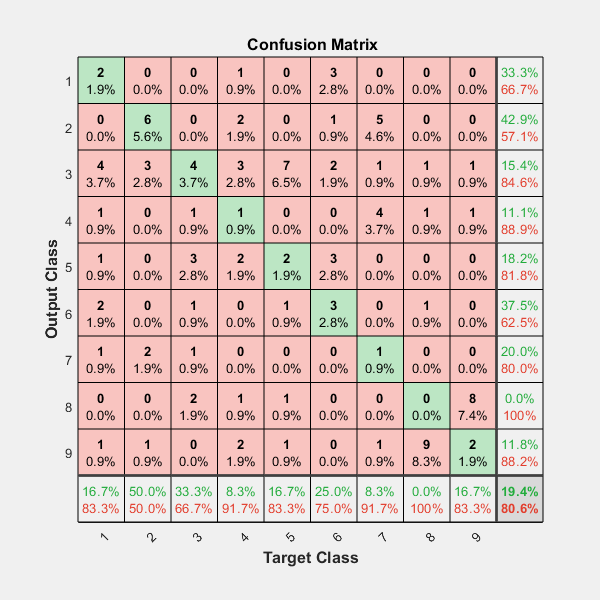

figure(1);
p1 = plotconfusion(Ytest_cat, Ytest_pred_cat);

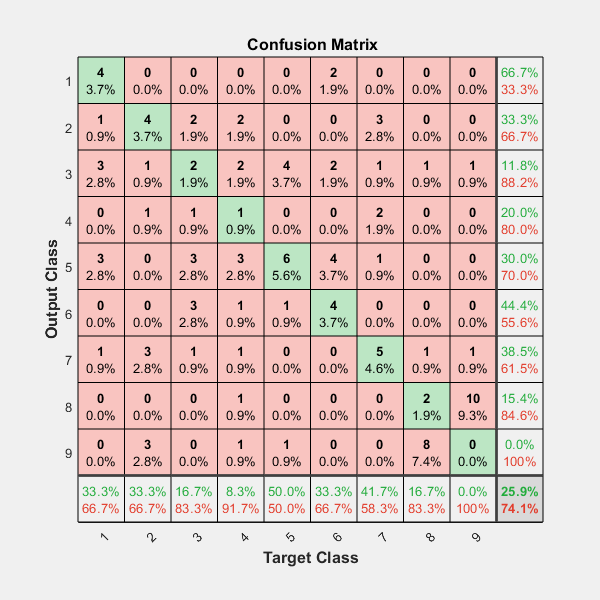

figure(2);
p2 = plotconfusion(Ytest_cat, Ytest_pred_cat2);

Can you find out how to interpret the confusion matrix in this case?  

Words 5 & 7 have the highest scores on predicting correctly on theirselves. Word 7 has nog been predicted as word 5, and word 5 has only once been predicted incorrectly as word 7.